clear 
clc

**Task 2: Numerical approximations of **$\mathbb{E}[Q(u)]$

`1.Richardson Extrapolation`

We want to estimate the bias, i.e.

                        
$$Q(u_h)-Q(u) = a_1h^p + \mathcal{O}(h^r)$$


for some $r>p$. Using Richardson extrapolation, we can obtain an approximation of the bias that is $r^{\text{th}}$-order accurate. For example

            (I)     $Q(u_h) - Q(u) = a_1h^p + a_2h^r+\text{h.o.t.}$

           (II)     $Q(u_{h/2}) - Q(u) = \frac{a_1}{2^p}h^p +  \frac{a_2}{2^p}h^r+\text{h.o.t.}$

Subtracting (II) from (I) yields

                
$$Q(u_h) - Q(u_{h/2})= \left(1-\frac{1}{2^p}\right)a_1h^p + \mathcal{O}(h^r)$$


such that the bias is approximately

                
$$\text{Bias} = Q(u_h)- Q(u) \approx \frac{1}{\left(1 - \frac{1}{2^p}\right)}\left(Q(u_h)- Q(u_{h/2})\right)$$


For an estimation of $p$ we compute $\mathbb{E}[Q(u_h) - Q(u)]$ for a range of $I$'s for a constant sample size of $M=10^3$.

`1. Model 1`

We will use the same randomness for $M$ samples.

M = 10^1; % Number of samples
randomfield = 1; % Random field type
RF_par = 0.5; %RF parameter
I_min = 64; % Minimal mesh size of x-axis discretization
I_max = 256; % Maximal mesh size of x-axis discretization
N = 10; % Mesh for random field discretization
% Dimensions of a: (Number of diff. I, max. I value for saving (1:i), samples) 
a = zeros([I_max-I_min I_max+1 M]); 
x_hat = linspace(0, 1, N + 1); % Discretization of x-axis for Random field
rng(1); % Set seed
a = -sqrt(3);
b = sqrt(3);
Y = a + (b-a).*rand(N, M);  % Samples for model 1

% Preallocation of solution array of PDE
u_h = zeros([I_max-I_min I_max+1 M]);

% Preallocation of solution array of the QoI
Q_uh = zeros([I_max-I_min M]);

% Preallocation of solution array of the QoI
MC_est = zeros([I_max-I_min 1]);

% Now we want to calculate for every sample k=1:M and every mesh size
% i=I_min:I_max a sample of the random field
for k=progress(1:M)
    for i=I_min:I_max
        x = linspace(0, 1, i+1);  % Evaluation of the random field on i+1 nodes
        
        % Model 1
        if randomfield == 1
            % for every sample we need an indicator function evaluated at
            % the different mesh sizes
            ind = zeros([length(x) N]);
            % Calculate for every node in the I mesh
            for l=1:length(x)
                % Check for every node in I mesh if its in [x^(k-1), x^(k)]
                for r=2:N+1
                    if (x(l) >= x_hat(r-1) & x(l) <= x_hat(r))
                        ind(l, r-1) = Y(r-1, k);
                    else
                        ind(l, r-1) = 0;
                    end
                end
            end
            stairs = crop(ind);
            
            for l=1:length(x)
                a(i-I_min+1, 1:i+1, k) = 1 + RF_par*stairs;
            end
        end
        %{
        % Only model 1 needs to be used
        if randomfield == 2
            C = Matern_specialcases_only(x, RF_par);
            [EVec, EVal] = eig(C);
            SV = zeros([i 1]);
            EVec = flip(EVec, 2);
            for p=1:i
                SV(p) = sqrt(EVal(i+1-p, i+1-p));
            end
            inner = zeros([i+1 N]);
            for p=1:N
                inner(:, p) = SV(p)*Y(p, k).*EVec(:, p);
            end
            kappa = sum(inner, 2);
            a(i-I_min+1, 1:i+1, k) = exp(kappa);
        end
        %}

        % Preallocate memory for tridiagonal matrix A
        A = zeros([i+1 i+1]);
        h = 1/i;
        for j=2:i
            A(j, j-1) = -a(i-I_min+1, j-1, k)/(h^2);
            A(j, j) = (a(i-I_min+1, j-1, k) + a(i-I_min+1, j+1, k))/(h^2);
            A(j, j+1) = -a(i-I_min+1, j+1, k)/(h^2);
        end

        F = zeros([i+1 1]);
        for p=1:i+1
            F(p) = 4*pi^2*cos(2*pi*x(p));
        end
                        
        u_h(i-I_min+1, 1:i+1, k) = A(2:i, :)\F(2:i);
        Q_uh(i-I_min+1, k) = h*sum(u_h(i-I_min+1, :, k));
        MC_est(i-I_min+1) = 1/M*sum(Q_uh(i-I_min+1, :));
        
    end
end

Processing:  000%  |                                        | 0/10it [00:00:00<Inf:NaN:NaN, Inf it/s]



bias = zeros([I_max/2-I_min 1]);
for i=progress(1:I_max/2-I_min)
    bias(i) = abs(MC_est(i) - MC_est(i + I_max/4));
end

Processing:  000%  |                                        | 0/64it [00:00:00<Inf:NaN:NaN, Inf it/s]


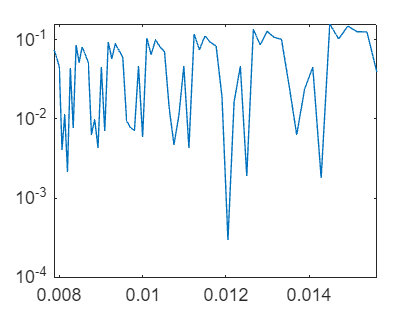


%plot(64:127, bias)
semilogy(1./(64:127), bias)



% Plots (works)
%{
for k=progress(1:M)
    figure()
    for i=I_min:I_max
        x = linspace(0, 1, i+1);
        plot(x, u_h(i-I_min+1, 1:i+1, k))
        hold on;
    end
end
%}